# Skipping functions call

Sometimes you may need to perform some plot only once or from time to time. In that case, you just need to "skip" the corresponding plot.

In the following example, we would like to plot an animated sinusoid and a moving square. The square poisition is only updated every 10 iterations.

clearvars
close all
clc

Setup an iterative display object.

id=iterativeDisplay;

Define parameters

bx=0.1;by=0.1;            % size of the box 
nFrames = 300;         % Number of animation frame
t=linspace(0,4*pi,200); % sinusoid time vector
w=1;                   % sinusoid pulsation (rad/s)

Main animation loop

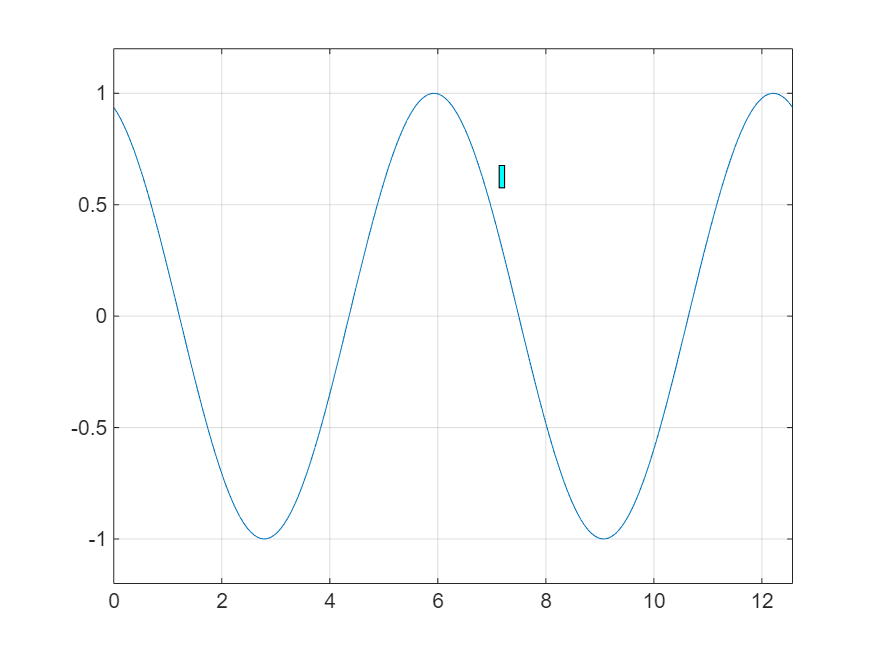

for i=1:nFrames
    % Sinusoid phase
    phi=8*pi*(i-1)/nFrames;
    ySinus=sin(w*t+phi);

    id.figure;
    id.newIteration;

    % Display sinusoid
    id.plot(t,ySinus);
    id.hold('on');
    id.grid('on')
    % Display box at different positions
    j=round((length(t)-1)*(i-1)/nFrames+1);
    x=t(j);y=ySinus(j);

    if mod(i-1,10)==0
        % Update (make sure something is displayed at first iteration
        id.patch([x x+bx x+bx x x],[y y y+by y+by y],'c');
    else
        % Do nothing
        id.skip('patch');
    end
    id.xlim([0 4*pi]);
    id.ylim([-1.2 1.2]);
    drawnow;
end